## A: Now, with drive+LDE

### A1. Prepair parameters for drive simulation

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

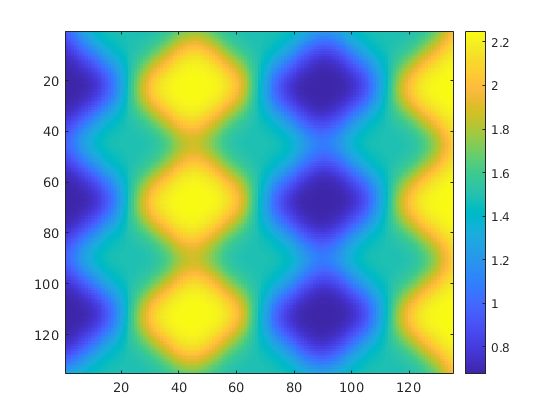

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

L6Ord_F = [50 33 15 33];
L6S_Drive = L6Ord_F*NS_L6/1e3 * StimulusFac;
L6C_Drive = L6Ord_F*NC_L6/1e3 * StimulusFac;
L6I_Drive = L6Ord_F*NI_L6/1e3 * StimulusFac;

% NOTE: Doing Gaussian blur
FigOn = false;
L6SFilt = SpatialGaussianFilt(OD_SMap,L6S_Drive,n_S_HC/8,FigOn);

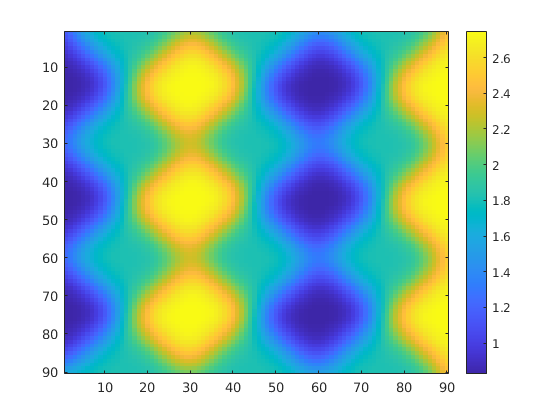

L6CFilt = SpatialGaussianFilt(OD_CMap,L6C_Drive,n_C_HC/8,FigOn);

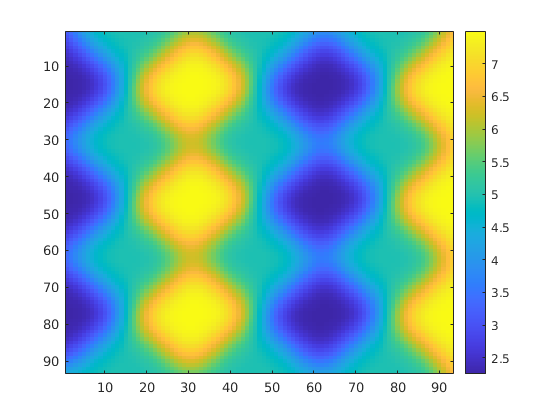

L6IFilt = SpatialGaussianFilt(OD_IMap,L6I_Drive,n_I_HC/8,FigOn);


rE_L6_Drive = [L6SFilt;L6CFilt];
rI_L6_Drive = L6IFilt;


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

### A2. Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .1; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .1; N_IEDly = floor(T_IEDly/dt); %% NOTE: Was both 0.5
T_EIDly = .1; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
          'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState('InSStr', InSStr,N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);      
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        tt = 0:dt:InpWin-dt;
        AdjlgnE = PhaseFRS(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
        AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                             + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                             + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                             + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                             + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.1; % Can't be too small for multiple phases
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        
        NWTrace(SampleInd).GE_I = GE_ITemp;
        NWTrace(SampleInd).GE_E = GE_ETemp;
        NWTrace(SampleInd).GI_I = GI_ITemp;
        NWTrace(SampleInd).GI_E = GI_ETemp;
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
        FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        % Precompute GE GI
        GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
        GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %                       

        GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
        GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %                       
        GE_ITemp(:,mVRecordInd) = GE_I;
        GE_ETemp(:,mVRecordInd) = GE_E;
        GI_ITemp(:,mVRecordInd) = GI_I;
        GI_ETemp(:,mVRecordInd) = GI_E;
        %record loop goes forward
        mVRecordInd = mVRecordInd + 1; 
    end
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end
toc
text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 10.1147

FrECNow = 34.4346

FrINow = 62.9229

Elapsed time is 2.437116 seconds.


SampleInd = 3

FrESNow = 9.4102

FrECNow = 25.9827

FrINow = 57.6598

Elapsed time is 3.907609 seconds.


SampleInd = 4

FrESNow = 9.1698

FrECNow = 29.2049

FrINow = 59.0195

Elapsed time is 6.152948 seconds.


SampleInd = 5

FrESNow = 9.8162

FrECNow = 34.8864

FrINow = 64.8260

Elapsed time is 7.721833 seconds.


SampleInd = 6

FrESNow = 9.0370

FrECNow = 31.1926

FrINow = 61.5516

Elapsed time is 9.997420 seconds.


SampleInd = 7

FrESNow = 8.8999

FrECNow = 32.6395

FrINow = 62.4835

Elapsed time is 11.577170 seconds.


SampleInd = 8

FrESNow = 8.9514

FrECNow = 32.7926

FrINow = 62.4373

Elapsed time is 13.879690 seconds.


SampleInd = 9

FrESNow = 8.9986

FrECNow = 35.1358

FrINow = 64.1022

Elapsed time is 15.402207 seconds.


SampleInd = 10

FrESNow = 9.0403

FrECNow = 32.0889

FrINow = 62.8836

Elapsed time is 17.700632 seconds.


SampleInd = 11

FrESNow = 8.8351

FrECNow = 30.7407

FrINow = 61.1007

Elapsed time is 19.197124 seconds.


SampleInd = 12

FrESNow = 9.0700

FrECNow = 34.8198

FrINow = 64.4583

Elapsed time is 21.482640 seconds.


SampleInd = 13

FrESNow = 9.5199

FrECNow = 36.9630

FrINow = 66.9326

Elapsed time is 23.058515 seconds.


SampleInd = 14

FrESNow = 8.5794

FrECNow = 30.1506

FrINow = 60.9180

Elapsed time is 25.236712 seconds.


SampleInd = 15

FrESNow = 8.3665

FrECNow = 28.4370

FrINow = 58.7629

Elapsed time is 26.671589 seconds.


SampleInd = 16

FrESNow = 9.1742

FrECNow = 30.8494

FrINow = 61.4730

Elapsed time is 28.856233 seconds.


SampleInd = 17

FrESNow = 8.6123

FrECNow = 30.7802

FrINow = 60.8510

Elapsed time is 30.353017 seconds.


SampleInd = 18

FrESNow = 9.3663

FrECNow = 35.1284

FrINow = 64.7312

Elapsed time is 32.635681 seconds.


SampleInd = 19

FrESNow = 9.0601

FrECNow = 36.4988

FrINow = 65.5752

Elapsed time is 34.218648 seconds.


SampleInd = 20

FrESNow = 8.6299

FrECNow = 30.5802

FrINow = 61.0730

Elapsed time is 36.470478 seconds.


SampleInd = 21

FrESNow = 9.3048

FrECNow = 33.2543

FrINow = 63.4917

Elapsed time is 37.991350 seconds.


Elapsed time is 37.992126 seconds.


SampleInd = 22

FrESNow = 8.7353

FrECNow = 30.4617

FrINow = 60.6521

Elapsed time is 2.103921 seconds.


SampleInd = 23

FrESNow = 8.9163

FrECNow = 32.5309

FrINow = 62.8697

Elapsed time is 3.597464 seconds.


SampleInd = 24

FrESNow = 9.2214

FrECNow = 31.5062

FrINow = 62.3818

Elapsed time is 5.754406 seconds.


SampleInd = 25

FrESNow = 8.8538

FrECNow = 30.4642

FrINow = 60.4486

Elapsed time is 7.218721 seconds.


SampleInd = 26

FrESNow = 9.1501

FrECNow = 34.9136

FrINow = 64.5161

Elapsed time is 9.409856 seconds.


SampleInd = 27

FrESNow = 8.7133

FrECNow = 30.4346

FrINow = 61.3921

Elapsed time is 10.937425 seconds.


SampleInd = 28

FrESNow = 9.1336

FrECNow = 36.1506

FrINow = 65.3023

Elapsed time is 13.184143 seconds.


SampleInd = 29

FrESNow = 9.0085

FrECNow = 33.0444

FrINow = 63.2605

Elapsed time is 14.733146 seconds.


SampleInd = 30

FrESNow = 8.9767

FrECNow = 34.2370

FrINow = 64.7150

Elapsed time is 16.989495 seconds.


SampleInd = 31

FrESNow = 8.7781

FrECNow = 28.5728

FrINow = 59.4196

Elapsed time is 18.464989 seconds.


SampleInd = 32

FrESNow = 9.2104

FrECNow = 34.4519

FrINow = 63.5704

Elapsed time is 20.680418 seconds.


SampleInd = 33

FrESNow = 8.8044

FrECNow = 29.6642

FrINow = 60.5596

Elapsed time is 22.159287 seconds.


SampleInd = 34

FrESNow = 9.4848

FrECNow = 36.6000

FrINow = 66.1024

Elapsed time is 24.394700 seconds.


SampleInd = 35

FrESNow = 9.1270

FrECNow = 32.5457

FrINow = 63.1611

Elapsed time is 25.887980 seconds.


SampleInd = 36

FrESNow = 8.7616

FrECNow = 29.5481

FrINow = 60.3006

Elapsed time is 28.045995 seconds.


SampleInd = 37

FrESNow = 9.1029

FrECNow = 30.4716

FrINow = 61.6279

Elapsed time is 29.523349 seconds.


SampleInd = 38

FrESNow = 9.3377

FrECNow = 38.6765

FrINow = 67.3373

Elapsed time is 31.839790 seconds.


SampleInd = 39

FrESNow = 8.9427

FrECNow = 32.0790

FrINow = 62.5205

Elapsed time is 33.364102 seconds.


SampleInd = 40

FrESNow = 8.8878

FrECNow = 31.9062

FrINow = 62.3147

Elapsed time is 35.535523 seconds.


SampleInd = 41

FrESNow = 9.2532

FrECNow = 31.0938

FrINow = 61.6557

Elapsed time is 37.033416 seconds.


Elapsed time is 37.034138 seconds.


SampleInd = 42

FrESNow = 8.7177

FrECNow = 32.9654

FrINow = 62.1344

Elapsed time is 2.202924 seconds.


SampleInd = 43

FrESNow = 9.5364

FrECNow = 35.7802

FrINow = 65.6446

Elapsed time is 3.793625 seconds.


SampleInd = 44

FrESNow = 9.1051

FrECNow = 31.1852

FrINow = 62.2662

Elapsed time is 5.958517 seconds.


SampleInd = 45

FrESNow = 9.1995

FrECNow = 38.8000

FrINow = 66.9904

Elapsed time is 7.523447 seconds.


SampleInd = 46

FrESNow = 8.5004

FrECNow = 27.8617

FrINow = 59.0750

Elapsed time is 9.611300 seconds.


SampleInd = 47

FrESNow = 9.1545

FrECNow = 34.7333

FrINow = 64.6063

Elapsed time is 11.163884 seconds.


SampleInd = 48

FrESNow = 8.9328

FrECNow = 32.9160

FrINow = 62.8073

Elapsed time is 13.352873 seconds.


SampleInd = 49

FrESNow = 9.0941

FrECNow = 34.6420

FrINow = 64.4236

Elapsed time is 14.878727 seconds.


SampleInd = 50

FrESNow = 9.1325

FrECNow = 32.6790

FrINow = 63.2397

Elapsed time is 17.139004 seconds.


SampleInd = 51

FrESNow = 8.9086

FrECNow = 32.3086

FrINow = 62.4396

Elapsed time is 18.679264 seconds.


SampleInd = 52

FrESNow = 9.0370

FrECNow = 33.6321

FrINow = 63.7160

Elapsed time is 20.826226 seconds.


SampleInd = 53

FrESNow = 8.7572

FrECNow = 30.6198

FrINow = 60.8140

Elapsed time is 22.279058 seconds.


SampleInd = 54

FrESNow = 8.8483

FrECNow = 32.5654

FrINow = 63.0246

Elapsed time is 24.482342 seconds.


SampleInd = 55

FrESNow = 9.0700

FrECNow = 33.2840

FrINow = 63.2790

Elapsed time is 26.048769 seconds.


SampleInd = 56

FrESNow = 8.8066

FrECNow = 30.4617

FrINow = 61.2487

Elapsed time is 28.221795 seconds.


SampleInd = 57

FrESNow = 9.2620

FrECNow = 37.4469

FrINow = 66.2851

Elapsed time is 29.800415 seconds.


SampleInd = 58

FrESNow = 9.0579

FrECNow = 33.3185

FrINow = 63.9288

Elapsed time is 31.987929 seconds.


SampleInd = 59

FrESNow = 9.1512

FrECNow = 35.5679

FrINow = 64.7242

Elapsed time is 33.519013 seconds.


SampleInd = 60

FrESNow = 8.3347

FrECNow = 29.1753

FrINow = 59.6855

Elapsed time is 35.646361 seconds.


SampleInd = 61

FrESNow = 8.9196

FrECNow = 32.2370

FrINow = 62.4095

Elapsed time is 37.227784 seconds.


Elapsed time is 37.228510 seconds.


SampleInd = 62

FrESNow = 8.9657

FrECNow = 32.0025

FrINow = 62.1829

Elapsed time is 2.189815 seconds.


SampleInd = 63

FrESNow = 9.1435

FrECNow = 32.8099

FrINow = 63.0293

Elapsed time is 3.804749 seconds.


SampleInd = 64

FrESNow = 9.1687

FrECNow = 36.4815

FrINow = 65.7001

Elapsed time is 6.118592 seconds.


SampleInd = 65

FrESNow = 9.2796

FrECNow = 37.7407

FrINow = 67.0089

Elapsed time is 7.782147 seconds.


SampleInd = 66

FrESNow = 8.6573

FrECNow = 29.9753

FrINow = 60.6567

Elapsed time is 9.891259 seconds.


SampleInd = 67

FrESNow = 8.4653

FrECNow = 28.7827

FrINow = 59.6161

Elapsed time is 11.336268 seconds.


SampleInd = 68

FrESNow = 9.3586

FrECNow = 37.0765

FrINow = 66.3522

Elapsed time is 13.554408 seconds.


SampleInd = 69

FrESNow = 8.9196

FrECNow = 29.9901

FrINow = 61.0591

Elapsed time is 15.076406 seconds.


SampleInd = 70

FrESNow = 8.7342

FrECNow = 34.3827

FrINow = 64.0953

Elapsed time is 17.349806 seconds.


SampleInd = 71

FrESNow = 9.2631

FrECNow = 37.2840

FrINow = 66.1972

Elapsed time is 18.891381 seconds.


SampleInd = 72

FrESNow = 8.7704

FrECNow = 25.8790

FrINow = 57.9766

Elapsed time is 20.974161 seconds.


SampleInd = 73

FrESNow = 9.0667

FrECNow = 38.8864

FrINow = 67.1361

Elapsed time is 22.608111 seconds.


SampleInd = 74

FrESNow = 9.0107

FrECNow = 31.5185

FrINow = 61.7551

Elapsed time is 24.757011 seconds.


SampleInd = 75

FrESNow = 9.3202

FrECNow = 37.2765

FrINow = 66.6944

Elapsed time is 26.368304 seconds.


SampleInd = 76

FrESNow = 8.2700

FrECNow = 27.5383

FrINow = 58.5894

Elapsed time is 28.488463 seconds.


SampleInd = 77

FrESNow = 8.8285

FrECNow = 35.8420

FrINow = 64.6826

Elapsed time is 30.044853 seconds.


SampleInd = 78

FrESNow = 9.6340

FrECNow = 39.0889

FrINow = 68.3200

Elapsed time is 32.354028 seconds.


SampleInd = 79

FrESNow = 8.2754

FrECNow = 25.1753

FrINow = 56.9129

Elapsed time is 33.842231 seconds.


SampleInd = 80

FrESNow = 9.7778

FrECNow = 41.1407

FrINow = 69.0878

Elapsed time is 36.190605 seconds.


SampleInd = 81

FrESNow = 8.6486

FrECNow = 26.7877

FrINow = 58.4923

Elapsed time is 37.671028 seconds.


Elapsed time is 37.671848 seconds.


SampleInd = 82

FrESNow = 8.7693

FrECNow = 35.0568

FrINow = 64.2248

Elapsed time is 2.274673 seconds.


SampleInd = 83

FrESNow = 8.7177

FrECNow = 29.8593

FrINow = 60.1596

Elapsed time is 3.799576 seconds.


SampleInd = 84

FrESNow = 9.0513

FrECNow = 32.5210

FrINow = 62.9067

Elapsed time is 6.130570 seconds.


SampleInd = 85

FrESNow = 9.0129

FrECNow = 34.3901

FrINow = 63.8432

Elapsed time is 7.744696 seconds.


SampleInd = 86

FrESNow = 8.6387

FrECNow = 27.3309

FrINow = 58.4715

Elapsed time is 9.849775 seconds.


SampleInd = 87

FrESNow = 9.2938

FrECNow = 33.3235

FrINow = 63.0547

Elapsed time is 11.358938 seconds.


SampleInd = 88

FrESNow = 9.1139

FrECNow = 40.4889

FrINow = 68.0194

Elapsed time is 13.613632 seconds.


SampleInd = 89

FrESNow = 9.0831

FrECNow = 34.8617

FrINow = 64.9185

Elapsed time is 15.199586 seconds.


SampleInd = 90

FrESNow = 8.8735

FrECNow = 36.2395

FrINow = 65.2746

Elapsed time is 17.402033 seconds.


SampleInd = 91

FrESNow = 8.0636

FrECNow = 23.0222

FrINow = 54.7763

Elapsed time is 18.841570 seconds.


SampleInd = 92

FrESNow = 9.4409

FrECNow = 42.7235

FrINow = 69.9133

Elapsed time is 21.215113 seconds.


SampleInd = 93

FrESNow = 8.6584

FrECNow = 26.3556

FrINow = 58.5085

Elapsed time is 22.696136 seconds.


SampleInd = 94

FrESNow = 9.0765

FrECNow = 34.4420

FrINow = 64.0837

Elapsed time is 24.873097 seconds.


SampleInd = 95

FrESNow = 8.4741

FrECNow = 27.8691

FrINow = 58.5386

Elapsed time is 26.290756 seconds.


SampleInd = 96

FrESNow = 9.3794

FrECNow = 38.2469

FrINow = 66.4470

Elapsed time is 28.514190 seconds.


SampleInd = 97

FrESNow = 8.8768

FrECNow = 32.7358

FrINow = 62.6361

Elapsed time is 29.995103 seconds.


SampleInd = 98

FrESNow = 9.0063

FrECNow = 28.9975

FrINow = 60.3214

Elapsed time is 32.096935 seconds.


SampleInd = 99

FrESNow = 9.2302

FrECNow = 36.0988

FrINow = 65.4365

Elapsed time is 33.613446 seconds.


SampleInd = 100

FrESNow = 8.7978

FrECNow = 30.9481

FrINow = 61.4453

Elapsed time is 35.767066 seconds.


SampleInd = 101

FrESNow = 9.3202

FrECNow = 37.7111

FrINow = 66.6875

Elapsed time is 37.323068 seconds.


Elapsed time is 37.323870 seconds.


SampleInd = 102

FrESNow = 9.0491

FrECNow = 31.3481

FrINow = 62.2083

Elapsed time is 2.175808 seconds.


SampleInd = 103

FrESNow = 8.6156

FrECNow = 29.2815

FrINow = 59.6254

Elapsed time is 3.673866 seconds.


SampleInd = 104

FrESNow = 9.3531

FrECNow = 36.2840

FrINow = 65.9660

Elapsed time is 5.891799 seconds.


SampleInd = 105

FrESNow = 8.2568

FrECNow = 27.1259

FrINow = 57.8888

Elapsed time is 7.315524 seconds.


SampleInd = 106

FrESNow = 9.7416

FrECNow = 36.5728

FrINow = 66.3661

Elapsed time is 9.581561 seconds.


SampleInd = 107

FrESNow = 8.7133

FrECNow = 30.9802

FrINow = 60.8672

Elapsed time is 11.097703 seconds.


SampleInd = 108

FrESNow = 8.3446

FrECNow = 29.9679

FrINow = 60.0301

Elapsed time is 13.187827 seconds.


SampleInd = 109

FrESNow = 8.9251

FrECNow = 34.2420

FrINow = 63.3229

Elapsed time is 14.709967 seconds.


SampleInd = 110

FrESNow = 8.9898

FrECNow = 36.2494

FrINow = 65.4642

Elapsed time is 16.897084 seconds.


SampleInd = 111

FrESNow = 8.7484

FrECNow = 30.0543

FrINow = 60.7515

Elapsed time is 18.362656 seconds.


SampleInd = 112

FrESNow = 9.0623

FrECNow = 33.0988

FrINow = 63.2304

Elapsed time is 20.528271 seconds.


SampleInd = 113

FrESNow = 9.1347

FrECNow = 35.0370

FrINow = 64.5115

Elapsed time is 22.087042 seconds.


SampleInd = 114

FrESNow = 9.1775

FrECNow = 31.6691

FrINow = 62.1875

Elapsed time is 24.225091 seconds.


SampleInd = 115

FrESNow = 8.5586

FrECNow = 32.8617

FrINow = 62.7055

Elapsed time is 25.752777 seconds.


SampleInd = 116

FrESNow = 9.0645

FrECNow = 34.7383

FrINow = 64.3311

Elapsed time is 27.933578 seconds.


SampleInd = 117

FrESNow = 8.7539

FrECNow = 31.7037

FrINow = 61.6487

Elapsed time is 29.416729 seconds.


SampleInd = 118

FrESNow = 9.3004

FrECNow = 34.1852

FrINow = 63.9866

Elapsed time is 31.683594 seconds.


SampleInd = 119

FrESNow = 8.8340

FrECNow = 30.0914

FrINow = 60.7400

Elapsed time is 33.172060 seconds.


SampleInd = 120

FrESNow = 8.9602

FrECNow = 35.5852

FrINow = 65.0688

Elapsed time is 35.395030 seconds.


SampleInd = 121

FrESNow = 9.0096

FrECNow = 29.6568

FrINow = 60.8302

Elapsed time is 36.836767 seconds.


Elapsed time is 36.837480 seconds.


SampleInd = 122

FrESNow = 9.0480

FrECNow = 34.9037

FrINow = 64.3219

Elapsed time is 2.220048 seconds.


SampleInd = 123

FrESNow = 9.0217

FrECNow = 33.9432

FrINow = 64.0467

Elapsed time is 3.714025 seconds.


SampleInd = 124

FrESNow = 9.2883

FrECNow = 33.1012

FrINow = 63.5079

Elapsed time is 5.951803 seconds.


SampleInd = 125

FrESNow = 9.0316

FrECNow = 30.2765

FrINow = 61.4707

Elapsed time is 7.415809 seconds.


SampleInd = 126

FrESNow = 8.7660

FrECNow = 33.8494

FrINow = 63.3900

Elapsed time is 9.644310 seconds.


SampleInd = 127

FrESNow = 9.1907

FrECNow = 33.9481

FrINow = 63.9681

Elapsed time is 11.206673 seconds.


SampleInd = 128

FrESNow = 9.3520

FrECNow = 37.0642

FrINow = 66.4886

Elapsed time is 13.433489 seconds.


SampleInd = 129

FrESNow = 8.8636

FrECNow = 28.6395

FrINow = 60.1596

Elapsed time is 14.984083 seconds.


SampleInd = 130

FrESNow = 8.9558

FrECNow = 34.9012

FrINow = 64.5184

Elapsed time is 17.210222 seconds.


SampleInd = 131

FrESNow = 8.8176

FrECNow = 27.9185

FrINow = 59.1814

Elapsed time is 18.680669 seconds.


SampleInd = 132

FrESNow = 9.3278

FrECNow = 32.2889

FrINow = 62.4812

Elapsed time is 20.862747 seconds.


SampleInd = 133

FrESNow = 9.2488

FrECNow = 35.6025

FrINow = 65.0040

Elapsed time is 22.416343 seconds.


SampleInd = 134

FrESNow = 8.7737

FrECNow = 29.9753

FrINow = 60.4740

Elapsed time is 24.543695 seconds.


SampleInd = 135

FrESNow = 8.7199

FrECNow = 35.1383

FrINow = 64.5578

Elapsed time is 26.091471 seconds.


SampleInd = 136

FrESNow = 9.2653

FrECNow = 39.8667

FrINow = 68.4935

Elapsed time is 28.392216 seconds.


SampleInd = 137

FrESNow = 8.1163

FrECNow = 23.4247

FrINow = 55.3821

Elapsed time is 29.846311 seconds.


SampleInd = 138

FrESNow = 9.1435

FrECNow = 38.2370

FrINow = 66.6620

Elapsed time is 32.082434 seconds.


SampleInd = 139

FrESNow = 9.1709

FrECNow = 37.1556

FrINow = 66.7268

Elapsed time is 33.659485 seconds.


SampleInd = 140

FrESNow = 8.9372

FrECNow = 27.2346

FrINow = 58.9386

Elapsed time is 35.760356 seconds.


SampleInd = 141

FrESNow = 9.0272

FrECNow = 35.8617

FrINow = 64.7266

Elapsed time is 37.291780 seconds.


Elapsed time is 37.292494 seconds.


SampleInd = 142

FrESNow = 8.9471

FrECNow = 31.6395

FrINow = 62.5598

Elapsed time is 2.156856 seconds.


SampleInd = 143

FrESNow = 8.4082

FrECNow = 29.6272

FrINow = 59.6693

Elapsed time is 3.600695 seconds.


SampleInd = 144

FrESNow = 9.8140

FrECNow = 39.1556

FrINow = 68.2576

Elapsed time is 5.865084 seconds.


SampleInd = 145

FrESNow = 8.3852

FrECNow = 26.2222

FrINow = 57.8680

Elapsed time is 7.291558 seconds.


SampleInd = 146

FrESNow = 8.7759

FrECNow = 32.2519

FrINow = 62.0812

Elapsed time is 9.445855 seconds.


SampleInd = 147

FrESNow = 9.0458

FrECNow = 30.2000

FrINow = 60.6475

Elapsed time is 10.901687 seconds.


SampleInd = 148

FrESNow = 9.1347

FrECNow = 33.3531

FrINow = 63.1009

Elapsed time is 13.106148 seconds.


SampleInd = 149

FrESNow = 9.1325

FrECNow = 37.4173

FrINow = 66.7592

Elapsed time is 14.639494 seconds.


SampleInd = 150

FrESNow = 8.7868

FrECNow = 27.0247

FrINow = 58.5154

Elapsed time is 16.686408 seconds.


SampleInd = 151

FrESNow = 9.1720

FrECNow = 37.1827

FrINow = 66.1094

Elapsed time is 18.217888 seconds.


SampleInd = 152

FrESNow = 8.7045

FrECNow = 30.5728

FrINow = 61.3944

Elapsed time is 20.353087 seconds.


SampleInd = 153

FrESNow = 9.0579

FrECNow = 30.7531

FrINow = 61.4129

Elapsed time is 21.822329 seconds.


SampleInd = 154

FrESNow = 8.6420

FrECNow = 33.2370

FrINow = 62.5275

Elapsed time is 24.028318 seconds.


SampleInd = 155

FrESNow = 9.0941

FrECNow = 35.4469

FrINow = 65.1983

Elapsed time is 25.560279 seconds.


SampleInd = 156

FrESNow = 9.1567

FrECNow = 31.8741

FrINow = 62.4881

Elapsed time is 27.709654 seconds.


SampleInd = 157

FrESNow = 8.9778

FrECNow = 30.1580

FrINow = 60.6382

Elapsed time is 29.194938 seconds.


SampleInd = 158

FrESNow = 9.4343

FrECNow = 35.0864

FrINow = 64.9416

Elapsed time is 31.403417 seconds.


SampleInd = 159

FrESNow = 8.7506

FrECNow = 28.8272

FrINow = 59.6416

Elapsed time is 32.842742 seconds.


SampleInd = 160

FrESNow = 8.7276

FrECNow = 33.1136

FrINow = 62.8304

Elapsed time is 34.975580 seconds.


SampleInd = 161

FrESNow = 9.7064

FrECNow = 40.6963

FrINow = 69.8624

Elapsed time is 36.585127 seconds.


Elapsed time is 36.585847 seconds.


SampleInd = 162

FrESNow = 8.5421

FrECNow = 27.4321

FrINow = 58.7282

Elapsed time is 2.049416 seconds.


SampleInd = 163

FrESNow = 9.0502

FrECNow = 35.7877

FrINow = 64.7219

Elapsed time is 3.627473 seconds.


SampleInd = 164

FrESNow = 9.0568

FrECNow = 30.4716

FrINow = 61.5655

Elapsed time is 5.798792 seconds.


SampleInd = 165

FrESNow = 8.4060

FrECNow = 31.8420

FrINow = 61.4221

Elapsed time is 7.358843 seconds.


SampleInd = 166

FrESNow = 9.3191

FrECNow = 34.2173

FrINow = 64.1508

Elapsed time is 9.548614 seconds.


SampleInd = 167

FrESNow = 8.7627

FrECNow = 30.5457

FrINow = 61.2279

Elapsed time is 11.032080 seconds.


SampleInd = 168

FrESNow = 9.2664

FrECNow = 34.1235

FrINow = 63.7923

Elapsed time is 13.316552 seconds.


SampleInd = 169

FrESNow = 8.6453

FrECNow = 31.0790

FrINow = 61.4938

Elapsed time is 14.880023 seconds.


SampleInd = 170

FrESNow = 9.2159

FrECNow = 36.0025

FrINow = 65.5128

Elapsed time is 17.105721 seconds.


SampleInd = 171

FrESNow = 8.6343

FrECNow = 29.2247

FrINow = 59.9075

Elapsed time is 18.570077 seconds.


SampleInd = 172

FrESNow = 8.8516

FrECNow = 30.8346

FrINow = 60.7030

Elapsed time is 20.777796 seconds.


SampleInd = 173

FrESNow = 9.5879

FrECNow = 40.1704

FrINow = 68.6299

Elapsed time is 22.434306 seconds.


SampleInd = 174

FrESNow = 8.6573

FrECNow = 31.9975

FrINow = 62.2731

Elapsed time is 24.652409 seconds.


SampleInd = 175

FrESNow = 9.0798

FrECNow = 29.3704

FrINow = 60.2891

Elapsed time is 26.199072 seconds.


SampleInd = 176

FrESNow = 9.0129

FrECNow = 35.0889

FrINow = 64.1461

Elapsed time is 28.455594 seconds.


SampleInd = 177

FrESNow = 8.8395

FrECNow = 30.5481

FrINow = 61.5285

Elapsed time is 29.973915 seconds.


SampleInd = 178

FrESNow = 9.6735

FrECNow = 42.2444

FrINow = 69.8300

Elapsed time is 32.328760 seconds.


SampleInd = 179

FrESNow = 8.9361

FrECNow = 31.4519

FrINow = 62.8813

Elapsed time is 33.803384 seconds.


SampleInd = 180

FrESNow = 8.4675

FrECNow = 28.4099

FrINow = 58.8022

Elapsed time is 35.904892 seconds.


SampleInd = 181

FrESNow = 9.3235

FrECNow = 39.7827

FrINow = 68.6022

Elapsed time is 37.514272 seconds.


Elapsed time is 37.515073 seconds.


SampleInd = 182

FrESNow = 8.1624

FrECNow = 23.1358

FrINow = 54.8040

Elapsed time is 2.000431 seconds.


SampleInd = 183

FrESNow = 9.5429

FrECNow = 36.6049

FrINow = 65.8851

Elapsed time is 3.540166 seconds.


SampleInd = 184

FrESNow = 8.5575

FrECNow = 30.2321

FrINow = 60.3515

Elapsed time is 5.662927 seconds.


SampleInd = 185

FrESNow = 8.7243

FrECNow = 32.0765

FrINow = 62.2893

Elapsed time is 7.150945 seconds.


SampleInd = 186

FrESNow = 9.3717

FrECNow = 37.5852

FrINow = 66.6482

Elapsed time is 9.348503 seconds.


SampleInd = 187

FrESNow = 8.5180

FrECNow = 28.1506

FrINow = 59.1282

Elapsed time is 10.741812 seconds.


SampleInd = 188

FrESNow = 8.7111

FrECNow = 34.2247

FrINow = 63.6166

Elapsed time is 12.888174 seconds.


SampleInd = 189

FrESNow = 9.1204

FrECNow = 31.6148

FrINow = 61.9378

Elapsed time is 14.339218 seconds.


SampleInd = 190

FrESNow = 9.2225

FrECNow = 41.5580

FrINow = 69.3814

Elapsed time is 16.586275 seconds.


SampleInd = 191

FrESNow = 9.1106

FrECNow = 30.2420

FrINow = 62.1251

Elapsed time is 18.090576 seconds.


SampleInd = 192

FrESNow = 8.1964

FrECNow = 27.5630

FrINow = 57.7454

Elapsed time is 20.210322 seconds.


SampleInd = 193

FrESNow = 9.0239

FrECNow = 34.6716

FrINow = 64.3959

Elapsed time is 21.749069 seconds.


SampleInd = 194

FrESNow = 8.8241

FrECNow = 32.7481

FrINow = 62.7610

Elapsed time is 23.932100 seconds.


SampleInd = 195

FrESNow = 9.2774

FrECNow = 34.8667

FrINow = 64.9717

Elapsed time is 25.533288 seconds.


SampleInd = 196

FrESNow = 9.0765

FrECNow = 32.7926

FrINow = 62.9460

Elapsed time is 27.706210 seconds.


SampleInd = 197

FrESNow = 8.8011

FrECNow = 31.2198

FrINow = 61.6071

Elapsed time is 29.226713 seconds.


SampleInd = 198

FrESNow = 9.1523

FrECNow = 36.0272

FrINow = 65.6816

Elapsed time is 31.503463 seconds.


SampleInd = 199

FrESNow = 8.3786

FrECNow = 29.3432

FrINow = 59.3849

Elapsed time is 33.015474 seconds.


SampleInd = 200

FrESNow = 9.3267

FrECNow = 35.1728

FrINow = 65.1497

Elapsed time is 35.208825 seconds.


SampleInd = 201

FrESNow = 8.6398

FrECNow = 31.1605

FrINow = 61.5424

Elapsed time is 36.730727 seconds.


Elapsed time is 36.731436 seconds.


save([SaveFolder,'DriveWkSp_SCSepa_Cconst_Conn.mat'],'CMatAll','EcplxInd');

### A3. read data, and get spike and mV

SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    load([DataFolder text],'NWTrace');
    
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    
%     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
%     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
%     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
%     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
    
%     GE_E = [GE_E, GE_ECurrent]; 
%     GE_I = [GE_I, GE_ICurrent];
%     GI_E = [GI_E, GI_ECurrent]; 
%     GI_I = [GI_I, GI_ICurrent];
    
end
load([DataFolder text],'PhaseE');
load( 'DriveWkSp_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

### A4. Plot some regular figures and prepare for MF

Check soome time dependency// cental hypercolum??

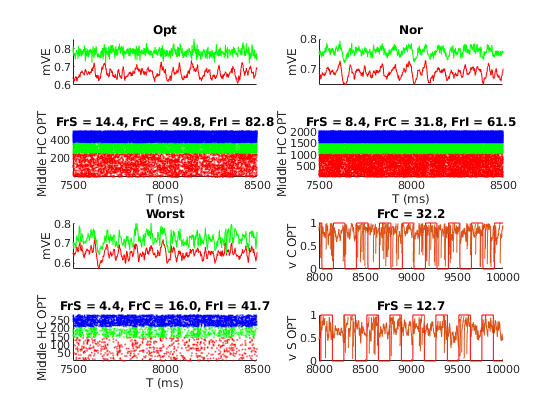

OptE = [L6SFilt>0.93*max(L6S_Drive);  L6CFilt>0.93*max(L6C_Drive)]';           
OptI =  L6IFilt'>0.93*max(L6I_Drive);
WorstE = [L6SFilt<1.1*min(L6S_Drive);  L6CFilt<1.1*min(L6C_Drive)]';         
WorstI =  L6IFilt'<1.1*min(L6I_Drive);
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1*n_S_HC & NnS.X<=2*n_S_HC;
MidRowS = NnS.Y>=1*n_S_HC & NnS.Y<=2*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1*n_C_HC & NnC.X<=2*n_C_HC;
MidRowC = NnC.Y>=1*n_C_HC & NnC.Y<=2*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1*n_I_HC & NnI.X<=2*n_I_HC;
MidRowI = NnI.Y>=1*n_I_HC & NnI.Y<=2*n_I_HC;
MidHCI= MidColI & MidRowI;

% SOpt = find(OptE & ~EcplxInd);
% scatterSOpt = find(ismember(SpE(:,1), SOpt));
% [~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
% FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);
% 
% COpt = find(OptE & EcplxInd);
% scatterCOpt = find(ismember(SpE(:,1), COpt));
% [~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
% FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [7500 8500];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');  
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');  
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');  
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);

### Plot Spatial maps: Plot

WinSize = 9000;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));


Determine On and Off t for Frs and mVs: 

Note, we get rid of the first 10ms of each interval

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
PhaseExc = 20;
mVPh = mod(repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), tMod);
OnOffmV = ~logical(floor(mVPh/MaxOnPhase)); % 1 for all on period, 0 for all off
OnmV  =  OnOffmV & ~(0< mVPh & mVPh<PhaseExc);
OffmV = ~OnOffmV & ~(MaxOnPhase< mVPh & mVPh<MaxOnPhase+PhaseExc);

SpPh = mod(PhaseE(SpE(:,1)) - T + SpE(:,2),tMod);
OnOffSpE =  ~logical(floor(SpPh/MaxOnPhase));
% OnSpE  =  OnOffSpE & ~(0<SpPh & SpPh<PhaseExc);
% OffSpE = ~OnOffSpE & ~(MaxOnPhase<SpPh & SpPh<MaxOnPhase+PhaseExc);
% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

% NnS.X = NnE.X(~EcplxInd); NnS.Y = NnE.Y(~EcplxInd);
% NnC.X = NnE.X(EcplxInd); NnC.Y = NnE.Y(EcplxInd);

FrERan = [0 55];
mVERan = [0.62 0.80];

Figure for ONOFF

First create an onoff vec for each spike

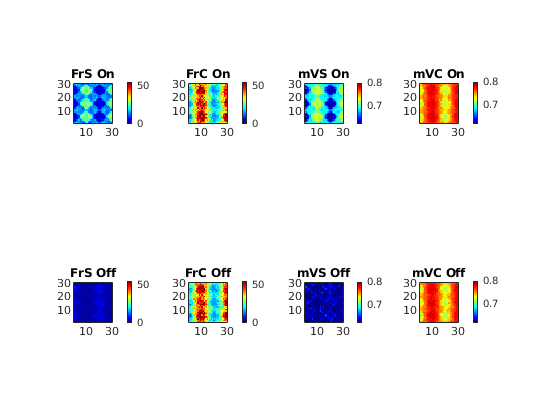

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates:S
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrSOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOnPixMat); title('FrS On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrSOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOffPixMat); title('FrS Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

% Firing rates: C
subplot 242
[FrCOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOnPixMat); title('FrC On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 246
[FrCOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOffPixMat); title('FrC Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% mVs: S
OnmVPhase = double(OnmV);
OnmVPhase(~OnmV) = nan;
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

subplot 243
[mVSOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOnPixMat); title('mVS On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

OffmVPhase = double(OffmV);
OffmVPhase(~OffmV) = nan;
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

subplot 247
[mVSOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOffPixMat); title('mVS Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

% mVs: C
subplot 244
[mVCOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOnPixMat); title('mVC On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

subplot 248
[mVCOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOffPixMat); title('mVC Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

Figure for All Average

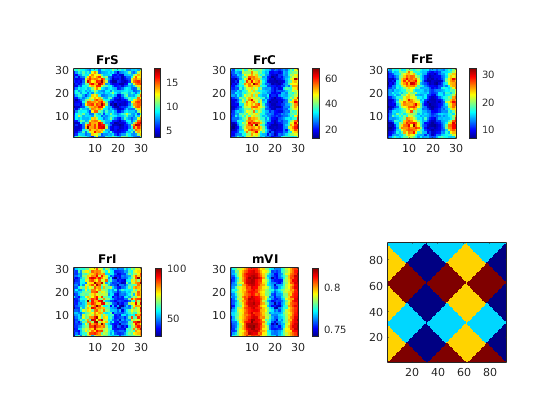

hFrVAll = figure('Name','Field_f&V');
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
%FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

subplot 231
[FrSPixMat,NnSPixel] = NeuVec2Pixel(FrE_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSPixMat); title('FrS')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar
subplot 232
[FrCPixMat,NnCPixel] = NeuVec2Pixel(FrE_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCPixMat); title('FrC')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(FrSPixMat*(1-CplxR)+ FrCPixMat*CplxR);
title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
% subplot 233
% imagesc(OD_EMap);axis square
% set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

Complex % Simple spikes

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
hSpCount = figure('Name','SpCountE')

hSpCount =   Figure (4: SpCountE) with properties:

      Number: 4
        Name: 'SpCountE'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


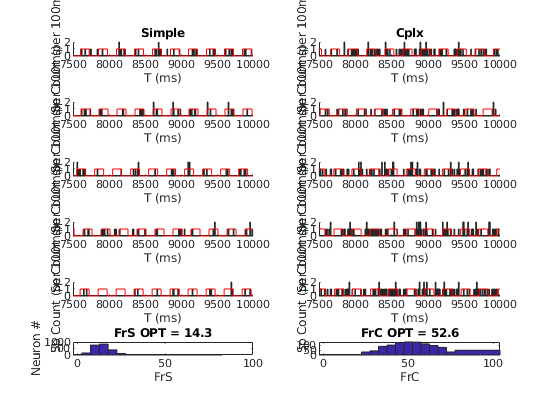

USE = [1,50,300,1000 1500];
for subInd = 1:5
    subplot(6,2,2*subInd-1)
    NeuInd = OPTS(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    if subInd ==1
        title('Simple')
    end
    
    subplot(6,2,2*subInd)
    NeuInd = OPTC(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    
    if subInd ==1
        title('Cplx')
    end
    
end
OPTS = OptE & ~EcplxInd;
OPTC = OptE & EcplxInd;
subplot(6,2,11)   
hist(FrE_temp(OPTS),0:5:80)
title(sprintf('FrS OPT = %.1f', mean(FrE_temp(OPTS))))
xlabel('FrS'); ylabel('Neuron #')
subplot(6,2,12)   
hist(FrE_temp(OPTC),0:5:80)
title(sprintf('FrC OPT = %.1f', mean(FrE_temp(OPTC))))
xlabel('FrC')

%save('DriveWkSp.mat')

### A5. MF linear equation for pixels: 1 Matrices

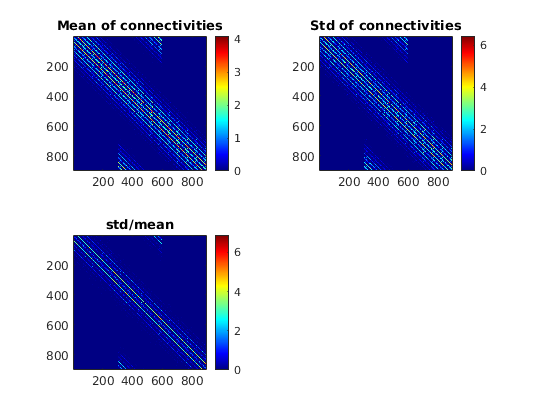

clear ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
      mVE mVEOff mVEOn mVI

load([DataFolder 'ConnPixel_Cconst.mat'])
% Present connectivity mats
figure
subplot 221
imagesc(C_SS_Pixel_Us)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_CS_Pixel_Us)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_CI_Pixel_Us)
axis square
colorbar
title('std/mean')


PixNum = NPixX*N_HC * NPixY*N_HC;
FrSPixVec    = reshape(FrSPixMat,  PixNum,1);
FrSOnPixVec  = reshape(FrSOnPixMat,PixNum,1);
FrSOffPixVec = reshape(FrSOffPixMat,PixNum,1);
FrCPixVec    = reshape(FrCPixMat,  PixNum,1);
FrCOnPixVec  = reshape(FrCOnPixMat,PixNum,1);
FrCOffPixVec = reshape(FrCOffPixMat,PixNum,1);
FrIPixVec    = reshape(FrIPixMat,  PixNum,1);

mVSOnPixVec  = reshape(mVSOnPixMat,PixNum,1);
mVSOffPixVec = reshape(mVSOffPixMat,PixNum,1);
mVCOnPixVec  = reshape(mVCOnPixMat,PixNum,1);
mVCOffPixVec = reshape(mVCOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_SOn_Pixel = zeros(PixNum,1);
lambda_SOff_Pixel = zeros(PixNum,1);
lambda_COn_Pixel = zeros(PixNum,1);
lambda_COff_Pixel = zeros(PixNum,1);
L6S_Pixel = zeros(PixNum,1);
L6C_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
lambda_SOn_drive = lambda_EOn_drive(~EcplxInd); lambda_COn_drive = lambda_EOn_drive(EcplxInd);
lambda_SOff_drive = lambda_EOff_drive(~EcplxInd); lambda_COff_drive = lambda_EOff_drive(EcplxInd);
rS_L6_Drive = rE_L6_Drive(~EcplxInd); rC_L6_Drive = rE_L6_Drive(EcplxInd);
for PixInd = 1:PixNum
    lambda_SOn_Pixel(PixInd)  = mean(lambda_SOn_drive(NnSPixel.Vec == PixInd));
    lambda_SOff_Pixel(PixInd) = mean(lambda_SOff_drive(NnSPixel.Vec == PixInd));
    lambda_COn_Pixel(PixInd)  = mean(lambda_COn_drive(NnCPixel.Vec == PixInd));
    lambda_COff_Pixel(PixInd) = mean(lambda_COff_drive(NnCPixel.Vec == PixInd));
    L6S_Pixel(PixInd) = mean(rS_L6_Drive(NnSPixel.Vec == PixInd));
    L6C_Pixel(PixInd) = mean(rC_L6_Drive(NnCPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive_Pre;

Below need work

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + 2*PixNum;
FrPreUse = FrSOffPixVec(FrPreUseDim - 2*PixNum); 
%FrPreUse = FrEOffLIF(FrPreUseDim - PixNum); 
FrPreUse = [];

### A6. Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
      C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
      C_SS_Fix_Bd C_SC_Fix_Bd C_CS_Fix_Bd C_CC_Fix_Bd...
      C_SI_Fix_Bd C_CI_Fix_Bd C_IS_Fix_Bd C_IC_Fix_Bd...
      COpt_Ind SOpt_Ind scatterCOpt scatterSOpt...
      ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE OnmV OffmV...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood SpPh...
      mVE mVEOff mVEOn mVI ...
      NWTrace AmbE_Events AdjlgnE AmbI_Events CMatAll ...
      EampaInp EnmdaInp GE_ETemp GE_ITemp IampaInp InmdaInp ...
      L6E_Events L6I_Events lgnE_Events lgnI_Events...
      mVECurrent mVICurrent mVETemp mVPh
save('AllMFPixPara_Paper2Tune.mat')   

## B Running HPC for LDE...

### B1. Load LDE computations and do Fr distributions

OPTPix = lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = lambda_SOn_Pixel<0.22;
OPTOBLBd_Pix = lambda_SOn_Pixel>0.33 & lambda_SOn_Pixel<0.42;
ORTOBLBd_Pix = lambda_SOn_Pixel>0.22 & lambda_SOn_Pixel<0.30;
NSPix = N_S/PixNum; NCPix = N_C/PixNum;
FrEPixNW = (FrSPixVec*NSPix + FrCPixVec*NCPix)/(NSPix+NCPix);
%FrEPixMF = (FrSMFV*NSPix + FrCMFV*NCPix)/(NSPix+NCPix);
fLDE_OPT = load('Paper2_LDE3.mat','f_EnIOut'); fLDE_OPT = fLDE_OPT.f_EnIOut;
fLDE_OBL = load('Paper2_LDE2.mat','f_EnIOut'); fLDE_OBL = fLDE_OBL.f_EnIOut;
fLDE_ORT = load('Paper2_LDE1.mat','f_EnIOut'); fLDE_ORT = fLDE_ORT.f_EnIOut;
FrLDE_opt = zeros(5,length(fLDE_OPT));
FrLDE_obl = zeros(5,length(fLDE_OPT));
FrLDE_ort = zeros(5,length(fLDE_OPT));
for LDEInd = 1:length(fLDE_OPT)
    if ~isempty(fLDE_OPT{LDEInd})
        FrLDE_opt(:,LDEInd) = mean(fLDE_OPT{LDEInd}(:,end-25:end),2);
        FrLDE_obl(:,LDEInd) = mean(fLDE_OBL{LDEInd}(:,end-25:end),2);
        FrLDE_ort(:,LDEInd) = mean(fLDE_ORT{LDEInd}(:,end-25:end),2);
    else
        FrLDE_opt(:,LDEInd) = nan;
        FrLDE_obl(:,LDEInd) = nan;
        FrLDE_ort(:,LDEInd) = nan;
    end
end
FrLDE_optE = ((FrLDE_opt(1,:)+FrLDE_opt(3,:))/2 * NSPix + ...
              (FrLDE_opt(2,:)+FrLDE_opt(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_oblE = ((FrLDE_obl(1,:)+FrLDE_obl(3,:))/2 * NSPix + ...
              (FrLDE_obl(2,:)+FrLDE_obl(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_ortE = ((FrLDE_ort(1,:)+FrLDE_ort(3,:))/2 * NSPix + ...
              (FrLDE_ort(2,:)+FrLDE_ort(4,:))/2 * NCPix)/(NSPix+NCPix);
% Do hist2
XOPT = linspace(12,51,30); YOPT = linspace(45,143,30);
NW_OPT = histcounts2(FrEPixNW(OPTPix),FrIPixVec(OPTPix),XOPT,YOPT);
LDE_OPT = histcounts2(FrLDE_optE,FrLDE_opt(5,:),XOPT,YOPT);
XOBL = linspace(5,32,30); YOBL = linspace(27,114,30);
NW_OBL = histcounts2(FrEPixNW(OBLPix),FrIPixVec(OBLPix),XOBL,YOBL);
LDE_OBL = histcounts2(FrLDE_oblE,FrLDE_obl(5,:),XOBL,YOBL);
XORT = linspace(2,20,30); YORT = linspace(14,92,30);
NW_ORT = histcounts2(FrEPixNW(ORTPix),FrIPixVec(ORTPix),XORT,YORT);
LDE_ORT = histcounts2(FrLDE_ortE,FrLDE_ort(5,:),XORT,YORT);


Figures for comparison

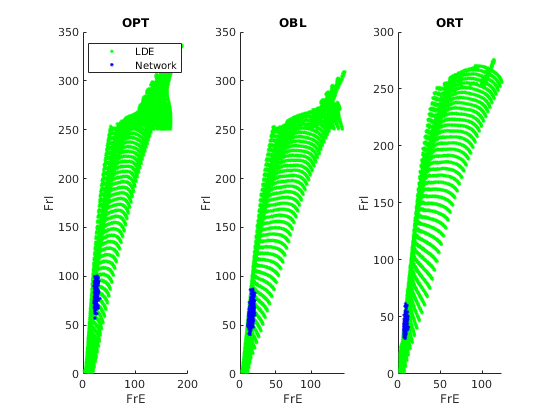

figure('Name','FrRanges')
subplot 131
hold on
scatter(FrLDE_optE,FrLDE_opt(5,:),'g.','DisplayName','LDE')
scatter(FrEPixNW(OPTPix),FrIPixVec(OPTPix),'b.','DisplayName','Network')
%scatter(FrEPixMF(OPTPix),FrIMFV(OPTPix),'r.','DisplayName','MF+V')
legend
xlabel('FrE');ylabel('FrI');
title('OPT')

subplot 132
hold on
scatter(FrLDE_oblE,FrLDE_obl(5,:),'g.')
scatter(FrEPixNW(OBLPix),FrIPixVec(OBLPix),'b.')
%scatter(FrEPixMF(OBLPix),FrIMFV(OBLPix),'r.')
xlabel('FrE');ylabel('FrI');
title('OBL')

subplot 133
hold on
scatter(FrLDE_ortE,FrLDE_ort(5,:),'g.')
scatter(FrEPixNW(ORTPix),FrIPixVec(ORTPix),'b.')
%scatter(FrEPixMF(ORTPix),FrIMFV(ORTPix),'r.')
xlabel('FrE');ylabel('FrI');
title('ORT')

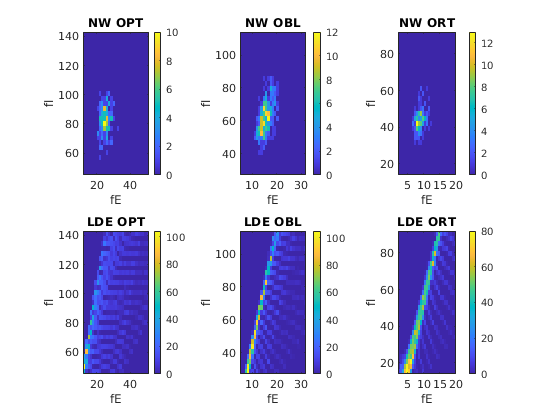


figure("Name",'FrDistb')
subplot 231
imagesc((XOPT(1:end-1)+XOPT(2:end))/2,(YOPT(1:end-1)+YOPT(2:end))/2,NW_OPT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OPT')
subplot 234
imagesc((XOPT(1:end-1)+XOPT(2:end))/2, (YOPT(1:end-1)+YOPT(2:end))/2, LDE_OPT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OPT')
subplot 232
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2, NW_OBL')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OBL')
subplot 235
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2,LDE_OBL')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OBL')
subplot 233
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,NW_ORT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW ORT')
subplot 236
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,LDE_ORT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE ORT')

## 2. Set up LDE firing rate functions

from HPC LDE computed results

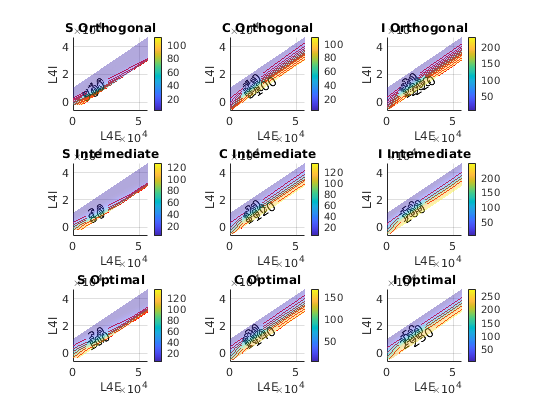

% Determine L4 Input from a range
% Expectation of kick numbers received by 1 neuron in each type
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
end
% Proportions between the distributions of kicks to SCI cells
% Assumption here: Total kicks received by the same pixel should be
% proportional to SCI
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);
LineFit = polyfit(L4Eall,L4Iall,1);
YRange = L4Iall - (LineFit(1)*L4Eall+LineFit(2)); % We plan to use 2 times of the range
Bdry = floor(max(abs(YRange))/100)*100;

L4ERange = 0:200:ceil(max(L4Eall)*2/100)*100;
L4IDiffRange = -12*Bdry:200:12*Bdry;
a1 = length(L4ERange); a2 = length(L4IDiffRange);

load(['Paper2_LDE1.mat'])
figure('Name','LDERateFunctions')
CtgrName = {'Orthogonal','Intemediate','Optimal'};
LDEFrVecS = zeros(length(L4ERcrd),3);
LDEFrVecC = zeros(length(L4ERcrd),3);
LDEFrVecI = zeros(length(L4ERcrd),3);
for Ctgr = 1:3
    load(['Paper2_LDE' num2str(Ctgr) '.mat'])
    L4EPlot = reshape(L4ERcrd,a2,a1);
    L4IPlot = reshape(L4IRcrd,a2,a1);
    FrLDE = zeros(length(f_EnIOut),5);
    for LDEInd = 1:length(f_EnIOut)
        if ~isempty(f_EnIOut{LDEInd})
            FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,end-25:end),2))';
        else
            FrLDE(LDEInd,:) = nan;
        end
    end
    % S rates
    subplot(3,3,(Ctgr-1)*3+1)
    LDEFrVecS(:,Ctgr) = ...
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true);
    
    % C rates
    subplot(3,3,(Ctgr-1)*3+2)
    LDEFrVecC(:,Ctgr) = ...
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'C',true); 
    
    % I rates
    subplot(3,3,(Ctgr-1)*3+3)
    LDEFrVecI(:,Ctgr) = ...
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'I',true); 
end

Create a function

L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400); 
L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
[L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
% 2D function now, depending on input of total E and I kick numbers
LDEFrfunc.S.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.C.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.I.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,3),L4EmeshX, L4ImeshY);

Maybe linear extrapolation?

## 3. Now Start Iteration

First, get an averaged Fr integration kernal

Write a function to smooth the integration kernel

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

PixLGNCtgr1 = LGNIndSpat(L6SFilt,unique(L6S_Drive),NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr2 = LGNIndSpat(PhaseFRS(OD_S)',unique(PhaseFRS(OD_S)),NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = PixLGNCtgr1*0.7 + PixLGNCtgr2*0.3;

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
% Classify Input for each pixel
% Get input spatial pattern for 3*3 and make a larger one

% PixCtgr = ORTPix + 2*OBLPix + 3*OPTPix + 4*ORTOBLBd_Pix + 5*OPTOBLBd_Pix;
% PixCtgrBool = [ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix];
figure('Name','function applying')
ShowField(PixLGNCtgr,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY)

% CtgrMap = [0,0,0.5; 0.5,0,0; 0,0.5,0; 1,0,1; 1,1,0];
% cbr = colorbar; cbr.Ticks = 1:5; cbr.TickLabels = {'ORT','OBL','OPT','Bdry12','Bdry23'};
% colormap(CtgrMap)

Give an intial condition, Now start

try a dot product here

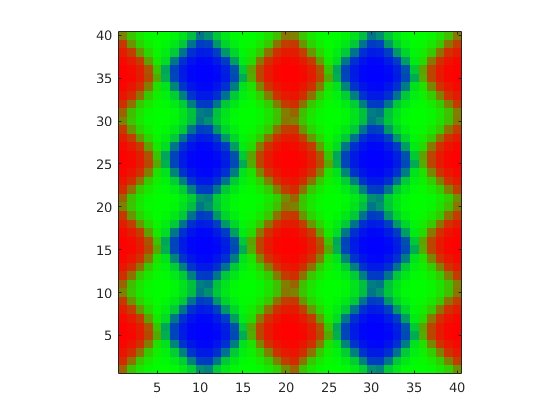

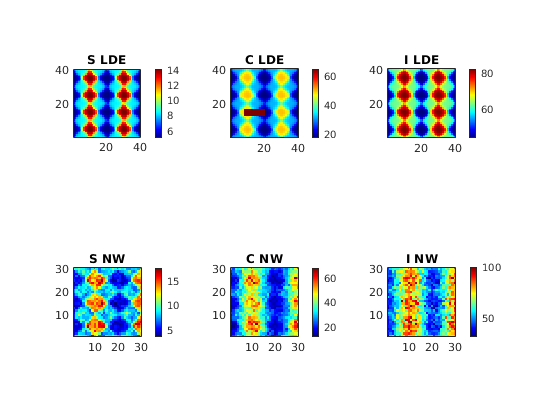

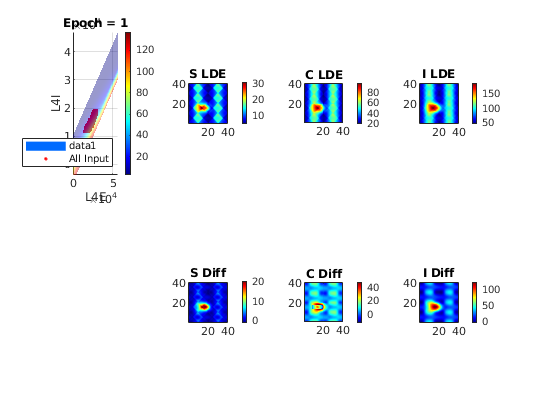

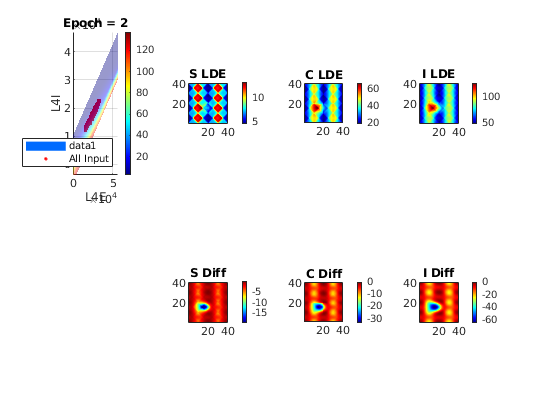

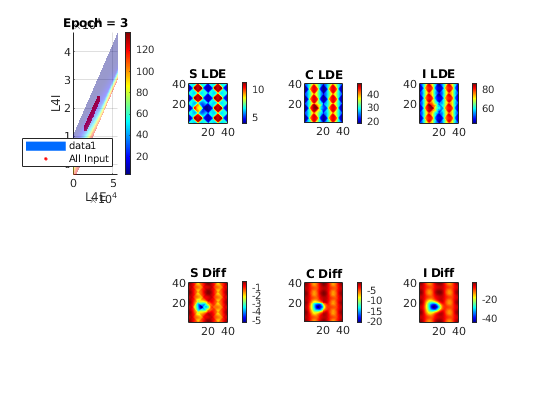

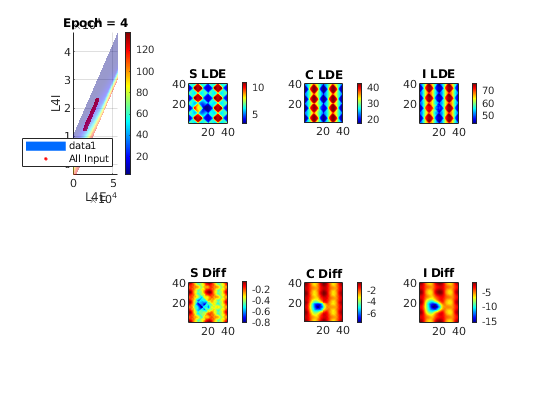

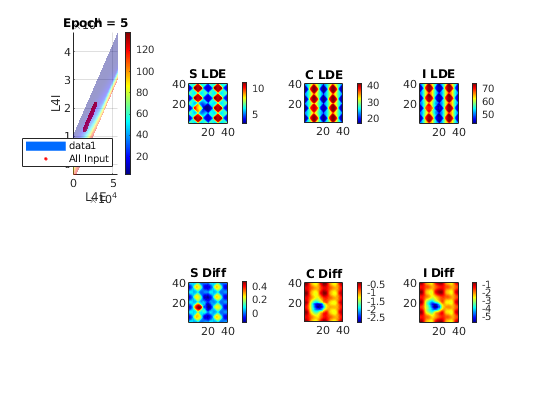

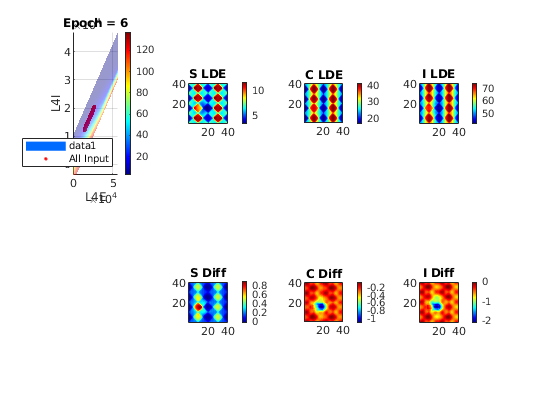

ORTPixLar = PixLGNCtgr(:,1) == 1;
OBLPixLar = PixLGNCtgr(:,2) == 1;
OPTPixLar = PixLGNCtgr(:,3) == 1;
MeanFrCtry = @(x1) [mean(x1(ORTPix)),mean(x1(OBLPix)),mean(x1(OPTPix))];

LDEIni.S = PixLGNCtgr * MeanFrCtry(FrSPixVec)';
LDEIni.C = PixLGNCtgr * MeanFrCtry(FrCPixVec)';
LDEIni.I = PixLGNCtgr * MeanFrCtry(FrIPixVec)';
% LDEIni.S = ORTPix*mean(FrSPixVec(ORTPix)) + OBLPix*mean(FrSPixVec(OBLPix)) + ...
%            OPTPix*mean(FrSPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrSPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrSPixVec(OPTOBLBd_Pix));
% LDEIni.C = ORTPix*mean(FrCPixVec(ORTPix)) + OBLPix*mean(FrCPixVec(OBLPix)) + ...
%            OPTPix*mean(FrCPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrCPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrCPixVec(OPTOBLBd_Pix));
% LDEIni.I = ORTPix*mean(FrIPixVec(ORTPix)) + OBLPix*mean(FrIPixVec(OBLPix)) + ...
%            OPTPix*mean(FrIPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrIPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrIPixVec(OPTOBLBd_Pix));
 
for IndX = 9:20
    for IndY = 14:17
        PixInd = (IndX-1)*40 + IndY;
        LDEIni.C(PixInd) = 65;
    end
end
% LDEIni.S = ones(size(LDEIni.S))*mean(LDEIni.S,'all')*2/3;
% LDEIni.C = ones(size(LDEIni.C))*mean(LDEIni.C,'all')*2/3;
% LDEIni.I = ones(size(LDEIni.I))*mean(LDEIni.I,'all')*2/3;
% LDEIni.S = FrSPixVec;
% LDEIni.C = FrCPixVec;
% LDEIni.I = FrIPixVec;
figure('Name','LDE Initial')
subplot 231
ShowField(LDEIni.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 232
ShowField(LDEIni.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
subplot 233
ShowField(LDEIni.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 234
ShowField(FrSPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S NW')
subplot 235
ShowField(FrCPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C NW')
subplot 236
ShowField(FrIPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I NW')
% Iteration
p = 0.2; % 1-p for the original input
Epoc = 20;
LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;

for Epc = 1:Epoc
    figure('Name','LDE Iteration')
    LDEUse = LDEItr{Epc};
    L4EUse = C_SS_mean*LDEUse.S  - diag(C_SS_mean).*LDEUse.S + ...
             C_CS_mean*LDEUse.S  - diag(C_CS_mean).*LDEUse.S + ...
             C_IS_mean*LDEUse.S  - diag(C_IS_mean).*LDEUse.S + ...
             C_SC_mean*LDEUse.C  - diag(C_SC_mean).*LDEUse.C + ...
             C_CC_mean*LDEUse.C  - diag(C_CC_mean).*LDEUse.C + ...
             C_IC_mean*LDEUse.C  - diag(C_IC_mean).*LDEUse.C ;    
    L4IUse = C_SI_mean*LDEUse.I  - diag(C_SI_mean).*LDEUse.I + ...
             C_CI_mean*LDEUse.I  - diag(C_CI_mean).*LDEUse.I + ...
             C_II_mean*LDEUse.I  - diag(C_II_mean).*LDEUse.I ;
    % See where does the input stands
    subplot 241
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true,false);
    hold on
    scatter(L4EUse,L4IUse,'r.','Displayname','All Input');
%     scatter(L4EUse(ORTPix),L4IUse(ORTPix),'r.','Displayname','ort');
%     scatter(L4EUse(OBLPix),L4IUse(OBLPix),'g.','Displayname','obl');
%     scatter(L4EUse(OPTPix),L4IUse(OPTPix),'b.','Displayname','opt');
%     scatter(L4EUse(ORTOBLBd_Pix),L4IUse(ORTOBLBd_Pix),'gd','Displayname','bd1');
%     scatter(L4EUse(OPTOBLBd_Pix),L4IUse(OPTOBLBd_Pix),'bx','Displayname','bd2');
    legend('Location','southeast')
    title(sprintf('Epoch = %d', Epc))
    hold off
    % Refer to functions
    LDEOut = struct('S',[],'C',[],'I',[]);
    LDEOut.S = LDEIterFunc(L4EmeshX, L4ImeshY,...
                           LDEFrfunc.S.ORT,LDEFrfunc.S.OBL,LDEFrfunc.S.OPT,...
                           L4EUse,L4IUse,LDEUse.S,...
                           PixLGNCtgr);
                           %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc(L4EmeshX, L4ImeshY,...
                           LDEFrfunc.C.ORT,LDEFrfunc.C.OBL,LDEFrfunc.C.OPT,...
                           L4EUse,L4IUse,LDEUse.C,...
                           PixLGNCtgr);
                           % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc(L4EmeshX, L4ImeshY,...
                           LDEFrfunc.I.ORT,LDEFrfunc.I.OBL,LDEFrfunc.I.OPT,...
                           L4EUse,L4IUse,LDEUse.I,...
                           PixLGNCtgr);
                           %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct('S',LDEOut.S*p + LDEUse.S*(1-p),...
                     'C',LDEOut.C*p + LDEUse.C*(1-p),...
                     'I',LDEOut.I*p + LDEUse.I*(1-p));
    LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
    subplot 242
    ShowField(LDEOut.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
    subplot 243
    ShowField(LDEOut.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
    subplot 244
    ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
    subplot 246
    ShowField(LDEEpoOut{Epc+1}.S - LDEEpoOut{Epc}.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S Diff')
    subplot 247
    ShowField(LDEEpoOut{Epc+1}.C - LDEEpoOut{Epc}.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C Diff')
    subplot 248
    ShowField(LDEEpoOut{Epc+1}.I - LDEEpoOut{Epc}.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I Diff')
    drawnow
    pause(0.5)
end

One more fig for diff

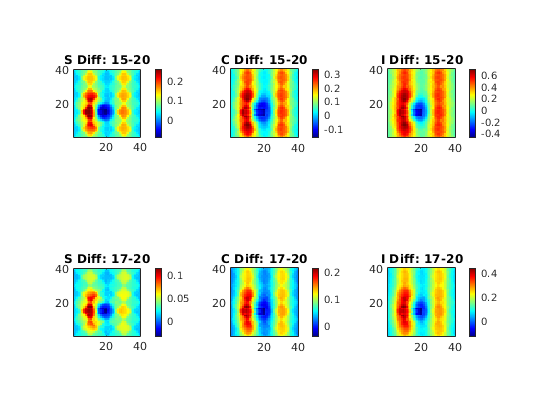

figure('Name','epoch diff')
subplot 231
Ep1 = 15; Ep2 = 17; Ep3 = 20;
ShowField(LDEEpoOut{Ep1}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
          N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep1, Ep3))
subplot 232
ShowField(LDEEpoOut{Ep1}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
          N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep1, Ep3))
subplot 233
ShowField(LDEEpoOut{Ep1}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
         N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep1, Ep3))

subplot 234
ShowField(LDEEpoOut{Ep2}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
          N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep2, Ep3))
subplot 235
ShowField(LDEEpoOut{Ep2}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
          N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep2, Ep3))
subplot 236
ShowField(LDEEpoOut{Ep2}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
         N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep2, Ep3))

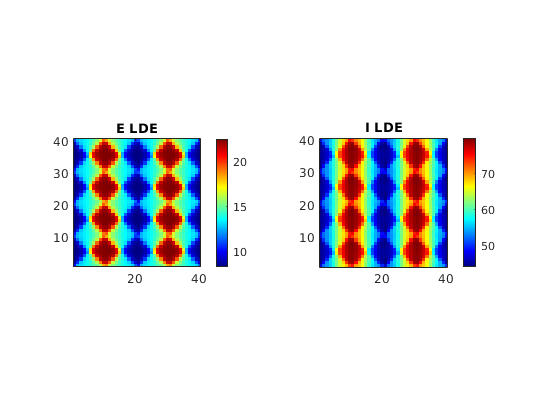


figure('Name','EImap')
subplot 121
ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
                   1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'E LDE')
subplot 122
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')

 Compute Frs

LDENames = fieldnames(LDEOut)

LDENames = 3×1 cell array
    {'S'}
    {'C'}
    {'I'}


for Nid = 1:length(LDENames)
    CurrField = LDEOut.(LDENames{Nid});
    CurrMap = reshape(CurrField,N_HCOut*NPixX,N_HCOut*NPixY);
    CurrMapShrk = CurrMap(1:N_HC*NPixY,1:N_HC*NPixX);
    LDEOutShrk.(LDENames{Nid}) = reshape(CurrMapShrk,N_HC*NPixY*N_HC*NPixX,1);
    MeanFrCtry(LDEOutShrk.(LDENames{Nid}))
end

ans =     4.6808    7.5624   12.7312


ans =    18.4880   29.4892   42.7685


ans =    45.9903   60.7937   77.7471


### 4. Comparison between MF+V and LIF-only

LDEUse = LDEItr{20};
L4lifSE = C_SS_mean*LDEUse.S + C_SC_mean*LDEUse.C;
L4lifSI = C_SI_mean*LDEUse.I ;
L4lifCE = C_CS_mean*LDEUse.S + C_CC_mean*LDEUse.C;
L4lifCI = C_CI_mean*LDEUse.I ;
L4lifIE = C_IS_mean*LDEUse.S + C_IC_mean*LDEUse.C;
L4lifII = C_II_mean*LDEUse.I ;

Now consider a pixel containing 3 neurons: S C I

InputCtgr = 3; PixInd = 355; % pixel and input category
FL6_One = unique(L6Ord_F)/1e3;
rL6SU = NS_L6*FL6_One(InputCtgr); 
rL6CU = NC_L6*FL6_One(InputCtgr);
rL6IU = NI_L6*FL6_One(InputCtgr);
L4SE = L4lifSE(PixInd)/1e3; L4CE = L4lifCE(PixInd)/1e3; L4IE = L4lifIE(PixInd)/1e3;
L4SI = L4lifSI(PixInd)/1e3; L4CI = L4lifCI(PixInd)/1e3; L4II = L4lifII(PixInd)/1e3;

LIFSimuT = 40*1e3; TimeFrac = 1/(LIFSimuT/1e3)/LGNFreq;
lgn_Events    = PoissonInputForNetwork(3, 45*[N_Slgn;N_Clgn;N_Ilgn]/1e3 ,LIFSimuT*TimeFrac,dt);
AmbPix_Events = PoissonInputForNetwork(3,[rS_amb;rC_amb;rI_amb],LIFSimuT*TimeFrac,dt);
L6Pix_Events  = PoissonInputForNetwork(3,[rL6SU; rL6CU; rL6IU], LIFSimuT*TimeFrac,dt);
L4Pix_EventsE = PoissonInputForNetwork(3,[L4SE; L4CE; L4IE],LIFSimuT*TimeFrac,dt);
L4Pix_EventsI = PoissonInputForNetwork(3,[L4SI; L4CI; L4II],LIFSimuT*TimeFrac,dt);
gL = [gL_E*ones(2,1); gL_I*ones(1)];

Can precompute all Gs...

% Now adjust lgn to S
lgn_SOnOff = [0.045, 0.0675, 0.09;
              0.045, 0.0225, 0.00];
lgn_SOnOffU = lgn_SOnOff(:,InputCtgr);
lgnAdj = lgn_SOnOffU./lgn_SOnOff(:,1);

TCyc = floor(1/TimeFrac);
VRcdCyc = cell(TCyc,1);
for TInt = 1:TCyc
VRcd = zeros(size())
lgnPix_Events = lgn_Events(:,randperm(size(lgnPix_Events,2))); 

winAMPA = 0:dt:tau_ampa_D*3;
winNMDA = 0:dt:tau_nmda_D*3;
winGABA = 0:dt:tau_gaba_D*3;
KerAMPA = 1/(tau_ampa_D-tau_ampa_R) * (exp(-winAMPA/tau_ampa_D) - exp(-winAMPA/tau_ampa_R));
KerNMDA = 1/(tau_nmda_D-tau_nmda_R) * (exp(-winNMDA/tau_nmda_D) - exp(-winNMDA/tau_nmda_R));
KerGABA = 1/(tau_gaba_D-tau_gaba_R) * (exp(-winGABA/tau_gaba_D) - exp(-winGABA/tau_gaba_R));
KerAMPA = KerAMPA / (sum(KerAMPA)*dt);
KerNMDA = KerNMDA / (sum(KerNMDA)*dt);
KerGABA = KerGABA / (sum(KerGABA)*dt);
% Incorporate L4 and other input
ampaInp = single([S_Elgn * lgnPix_Events(1:2,:);            S_Ilgn * lgnPix_Events(3,:)]...
               +  S_amb  * AmbPix_Events ... % S_amb identical for E and I
               + [S_EL6  * L6Pix_Events(1:2,:) * rhoE_ampa; S_IL6 * L6Pix_Events(3,:) * rhoI_ampa]...
               + [S_EE * L4Pix_EventsE(1:2,:) * rhoE_ampa; S_IE * L4Pix_EventsE(3,:) * rhoI_ampa]);
nmdaInp = single([S_EL6  * L6Pix_Events(1:2,:) * rhoE_nmda; S_IL6 * L6Pix_Events(3,:) * rhoI_nmda]...
               + [S_EE * L4Pix_EventsE(1:2,:) * rhoE_nmda; S_IE * L4Pix_EventsE(3,:) * rhoI_nmda]);
gabaInp = single([S_EI * L4Pix_EventsI(1:2,:);             S_II * L4Pix_EventsI(3,:)] );
%% Precompute All Conductances: Speed up by ifft/fft
n = size(ampaInp,2);
GAMPA = ifft(fft(ampaInp',n) .* repmat(fft(KerAMPA',n),1,3))';
GNMDA = ifft(fft(nmdaInp',n) .* repmat(fft(KerNMDA',n),1,3))';
GGABA = ifft(fft(gabaInp',n) .* repmat(fft(KerGABA',n),1,3))';

GE = GAMPA + GNMDA;  GI = GGABA;


end